# CIV102 BRIDGE DESIGN PROJECT: DESIGN CALCULATIONS: Design 0 Load Case 2

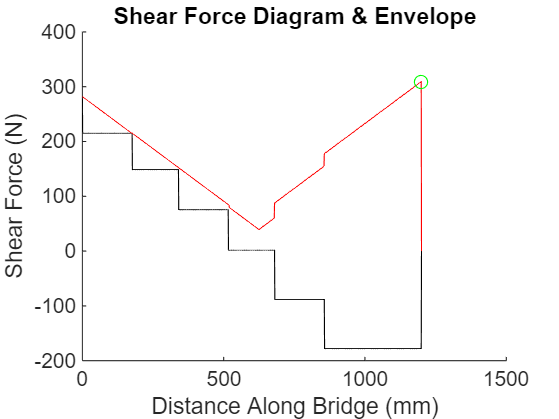

% GROUP MEMBERS: ALIZA AZAM, CHARLOTTE WINTER AND BOYI ZHANG

% THIS SCRIPT CONTAINS CODE FOR LOAD CASE 1, WHERE THE TOTAL TRAIN WEIGHT WILL BE
% 400 N. THIS TOTAL WEIGHT WILL BE EVENLY DIVIDED ACROSS THE SIX (6) TRAIN AXLES.

clear; close all;

%% Initialize Parameters
bridge_length = 1200;   % Length of the bridge
n = 1200;   % Discretize into 1 mm segments
P = 400;    % Total weight of the train [N]
x = linspace(0, bridge_length, n+1); % x-axis    

%% SFD, BMD Under Train Loading
x_train = [52, 228, 392, 568, 732, 908]; % train load locations
P_train = [1 1 1.1 1.1 1.35 1.35] * (P/6);

n_train = 345;    % number of train start locations
SFDi = zeros(n_train, n+1);     % 1 SFD for each train location
BMDi = zeros(n_train, n+1);     % 1 BMD for each train location

for i = 1:n_train
    x_start_loc = i - 52;  % Starting location of the train
    x_train_mov = max(1, min(round(x_train + x_start_loc), n));

    % Step 1: Sum of moments at point A
    A_y = (sum(P_train .* x_train_mov)) / bridge_length; % Reaction force at 'y' solved 
    
    % Step 2: Sum of Fy equation, rearranged to solve for at point B, B_y
    B_y = sum(P_train) - A_y;
    initial_v = B_y; % initial shear force at left support (point B)

    % Step 3-5: Calculate shear force across segments
    SFDi(i, 1:x_train_mov(1)) = initial_v;
    for k = 1:length(P_train)
        initial_v = initial_v - P_train(k);
        
        if k < length(P_train)
            SFDi(i, x_train_mov(k):x_train_mov(k+1)) = initial_v;
        end
    end
    SFDi(i, x_train_mov(end):n) = initial_v;
    
    % Step 6: Update Point A (right supports) shear force value  
    initial_v = initial_v + A_y;
    SFDi(i, n+1) = initial_v;
    
    % Step 7: Integrate SFD to obtain BMD
    BMDi(i,:) = cumtrapz(SFDi(i,:));
end

SFD = max(abs(SFDi));   % the absolute maximum values of shear force at all locations
BMD = max(BMDi);        % the maximum value of all bending moments at all locations

% Plot SFD and BMD
figure(1)
hold on
plot(x, SFDi(2,:), "k")
plot(x, SFD, "r")   % SFD for maximum shear force
title("Shear Force Diagram & Envelope")
xlabel('Distance Along Bridge (mm)')
ylabel('Shear Force (N)')
[~, max_shear_idx] = max(SFD);  % find index of max moment
plot(x(max_shear_idx), SFD(max_shear_idx), "go") % plot max moment
legend("Shear Force", "Shear Force Envelope")
hold off

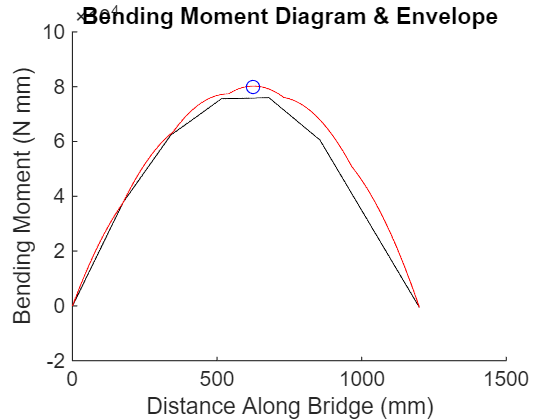


figure(2)
hold on
plot(x, BMDi(1,:), "k")
plot(x, BMD, "r")   % BMD for maximum bending moment
title("Bending Moment Diagram & Envelope")
xlabel('Distance Along Bridge (mm)')
ylabel('Bending Moment (N mm)')
[~, max_moment_idx] = max(BMD);  % find index of max moment
plot(x(max_moment_idx), BMD(max_moment_idx), "bo") % plot max moment
legend("Bending Moment Force", "Bending Moment Envelope")
hold off


%% Calculate Sectional Properties
% Step 1: Find centroidal axis of i number of rectangles
b = [100, 1.27, 1.27, 5, 5, 80]; % base of rectangle
height = [1.27, 73.73, 73.73, 1.27, 1.27, 1.27]; % height of rectangle
A_glue = b.*height; % Calculate area of each rectangle and store in array

% Step 2: Calculate for y bar
yi = [75.6, 38.1, 38.1, 74.4, 74.4, 0.635];
sum_yi_and_area = sum(A_glue.*yi);
ybar = sum_yi_and_area/sum(A_glue)

ybar = 41.4065


% Step 3: Calculate for y bottom and y top
h_tot = 76.27; % Inputted Value
ybot = ybar

ybot = 41.4065

y_top = h_tot - ybar

y_top = 34.8635


% Step 4: Calculate I (2nd Moment of Area)
I_nought = sum((b.*(height.^3))/12);
d = abs(ybar - yi);
I_parallel = sum(A_glue.*(d.^2));

I = I_nought + I_parallel

I = 4.1812e+05


% Step 5: Calculate Q at centroidal axes
d_i = [(20.065*2) (40.765)]; % Inputted Values (dist. from centroidal axes to centroid of each area (above or below))
A_i = [(1.27*40.13) (1.27*77.46)]; % Inputted Values (area of rectangles above or below centroidal axis)

Q_cent = sum(A_i.*d_i)

Q_cent = 6.0555e+03


% Step 6: Q at glue location
d_glue = 34.235; % Inputted Value (dist. from centroid of area of interest to y bar)
A_glue = 127; % The area or areas that would detach if the glue fails

Q_glue = A_glue*d_glue

Q_glue = 4.3478e+03


%% Calculate Applied Stress
V = SFD;
t_cent = 2*1.27; % Inputted Value (thickness @ axes of interest)
a_glue = 12.54; % Inputted Value (area where glue is used)

BMD_maxValue = max(BMD)

BMD_maxValue = 8.0231e+04

SFD_maxValue = max(SFD)

SFD_maxValue = 309.4639

S_top = (BMD_maxValue*y_top)/I

S_top = 6.6898

S_bot = (BMD_maxValue*ybot)/I

S_bot = 7.9453

T_cent = (SFD_maxValue.*Q_cent)./(I*t_cent)

T_cent = 1.7645

T_glue = (SFD_maxValue.*Q_glue)./(I*a_glue)

T_glue = 0.2566


% Material and Thin Plate Buckling Capacities
E = 4000;
thickness = 1.27;
poissons_ratio = 0.2;

% Given Material Properties 
S_tens = ones(1201, 1).*30; 
S_comp = ones(1201, 1).*6;
T_max = ones(1201, 1).*4;
T_gluemax = ones(1201, 1).*2; 

% Scenario #1 of Plate Buckling
k = 4;
b = 78.73; % Inputted Value (height)
S_buck1 = ((k*pi^2*E)/12*(1-(poissons_ratio^2)))*((thickness/b)^2)

S_buck1 = 3.2873


% Scenario #2 of Plate Buckling (one edge is restrained from moving while the other edge is free to move)
k = 0.425;
b = 10; % Inputted Value (height)
S_buck2 = ((k*pi^2*E) / (12*(1 - (poissons_ratio^2))))*(thickness/b)^2

S_buck2 = 23.4911


% Scenario #3 of Plate Buckling
k = 6;
b = 33.6; % Inputted Value (height)
S_buck3 = ((k*pi^2*E) / (12*(1 - (poissons_ratio^2))))*(thickness/b)^2

S_buck3 = 29.3756


% Scenario #4 of Plate Buckling
k = 5;
height = 76.27;
a = 400; % spacing of diaphragms
T_crit = ((5*pi^2*E)/(12*(1 - (poissons_ratio^2))))*(((thickness/height)^2) + ((thickness/a)^2))

T_crit = 4.9236

 
%% FOS
FOS_tens = min(S_tens'./ S_bot)

FOS_tens = 3.7758

FOS_comp = min(S_comp'./ S_top)

FOS_comp = 0.8969

FOS_shear = min(T_max'./T_cent)

FOS_shear = 2.2669

FOS_glue = min(T_gluemax'./T_glue)

FOS_glue = 7.7937

FOS_buck1 = min(S_buck1'./ S_top)

FOS_buck1 = 0.4914

FOS_buck2 = min(S_buck2'./ S_top)

FOS_buck2 = 3.5115

FOS_buck3 = min(S_buck3'./ S_top)

FOS_buck3 = 4.3911

FOS_buckV = min(T_crit'./ T_cent)

FOS_buckV = 2.7904


FOS = [FOS_tens, FOS_comp, FOS_shear, FOS_glue, FOS_buck1, FOS_buck2, FOS_buck3, FOS_buckV]

FOS =     3.7758    0.8969    2.2669    7.7937    0.4914    3.5115    4.3911    2.7904



%% Min FOS & the Failure Load P Fail
minFOS = min(FOS) % Min of all FOS values

minFOS = 0.4914

P_f = minFOS * P;
disp(P_f + " N")

196.5556 N


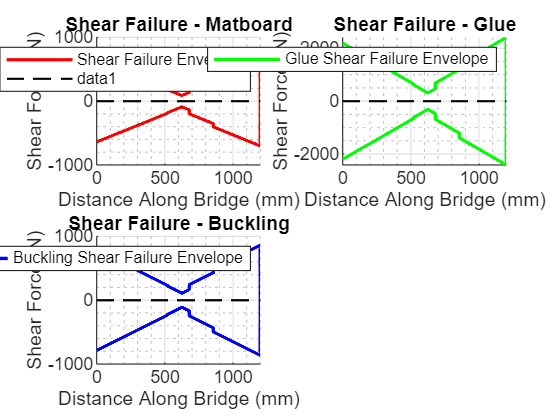

% Vfail and Mfail
Mf_tens = FOS_tens.*BMD;
Mf_comp = FOS_comp.*BMD;
Mf_buck1 = FOS_buck1.*BMD;
Mf_buck2 = FOS_buck2.*BMD;
Mf_buck3 = FOS_buck3.*BMD;
Vf_shear = FOS_shear.*SFD;
Vf_glue = FOS_glue.*SFD;
Vf_buckV = FOS_buckV.*SFD;

% Output plots of Vfail and Mfail
% Plot of Vfail
figure;
subplot(2, 2, 1);
hold on; grid on; grid minor;
plot(x, Vf_shear, 'r', 'LineWidth', 1.5);
plot(x, -Vf_shear, 'r', 'LineWidth', 1.5);
title('Shear Failure - Matboard');
xlabel('Distance Along Bridge (mm)');
ylabel('Shear Force (N)');
legend("Shear Failure Envelope")
plot([0, bridge_length], [0, 0], 'k--', 'LineWidth', 1);
hold off;

subplot(2, 2, 2);
hold on; grid on; grid minor;
plot(x, Vf_glue, 'g', 'LineWidth', 1.5);
plot(x, -Vf_glue, 'g', 'LineWidth', 1.5);
title('Shear Failure - Glue');
xlabel('Distance Along Bridge (mm)');
ylabel('Shear Force (N)');
legend("Glue Shear Failure Envelope")
plot([0, bridge_length], [0, 0], 'k--', 'LineWidth', 1);
hold off;
legend("Glue Shear Failure Envelope")

subplot(2, 2, 3);
hold on; grid on; grid minor;
plot(x, Vf_buckV, 'b', 'LineWidth', 1.5);
plot(x, -Vf_buckV, 'b', 'LineWidth', 1.5);
title('Shear Failure - Buckling');
xlabel('Distance Along Bridge (mm)');
ylabel('Shear Force (N)');
legend('Buckling Shear Failure Envelope')
plot([0, bridge_length], [0, 0], 'k--', 'LineWidth', 1);
hold off;

subplot(2,2,3)
legend("Buckling Shear Failure Envelope")

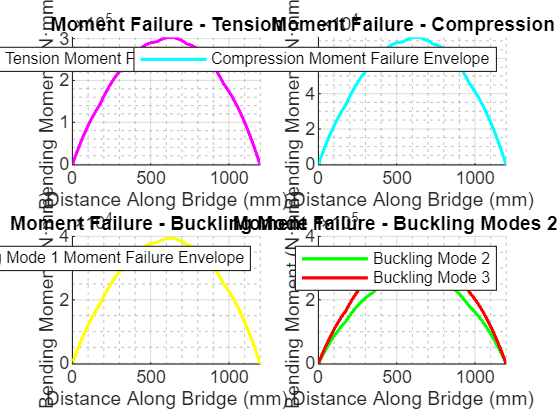


% Plot of Mfail
figure;
subplot(2, 2, 1);
hold on; grid on; grid minor;
plot(x, Mf_tens, 'm', 'LineWidth', 1.5);
title('Moment Failure - Tension');
xlabel('Distance Along Bridge (mm)');
ylabel('Bending Moment (N·mm)');
legend('Tension Moment Failure Envelope');
hold off;

subplot(2, 2, 2);
hold on; grid on; grid minor;
plot(x, Mf_comp, 'c', 'LineWidth', 1.5);
title('Moment Failure - Compression');
xlabel('Distance Along Bridge (mm)');
ylabel('Bending Moment (N·mm)');
legend('Compression Moment Failure Envelope');
hold off;

subplot(2, 2, 3);
hold on; grid on; grid minor;
plot(x, Mf_buck1, 'y', 'LineWidth', 1.5);
title('Moment Failure - Buckling Mode 1');
xlabel('Distance Along Bridge (mm)');
ylabel('Bending Moment (N·mm)');
legend('Buckling Mode 1 Moment Failure Envelope');
hold off;

subplot(2, 2, 4);
hold on; grid on; grid minor;
plot(x, Mf_buck2, 'g', 'LineWidth', 1.5);
plot(x, Mf_buck3, 'r', 'LineWidth', 1.5);
title('Moment Failure - Buckling Modes 2 & 3');
xlabel('Distance Along Bridge (mm)');
ylabel('Bending Moment (N·mm)');
legend('Buckling Mode 2', 'Buckling Mode 3');
hold off;